
fpms = [100 581]; %-- frames per millisecond
micronsPerPixel = [12.5 160]; %-- in x axis
z2xRatio = 3.7;

minAmplitudes = [-0.987 -0.98];
maxAmplitudes = [-0.98 -0.973];
smoothing = [1 1 3; 1 3 3];

trimmed1 = experiment1(10:end-5,40:end, 1:end);
trimmed2 = experiment2(1:end,1:39, 1:end);

imgSize = [size(trimmed2,1) size(trimmed2,2) size(trimmed1,3)];
pixelated1 = imresize3(trimmed1, imgSize);
pixelated2 = imresize3(trimmed2,imgSize);

smoothed1 = smooth3(-pixelated1, 'box', smoothing(1,:));
smoothed2 = smooth3(-pixelated2, 'box', smoothing(2,:));

scaled1 = ScaleImage(smoothed1,z2xRatio);
scaled2 = ScaleImage(smoothed2,z2xRatio);

normalized1 = NormalizeMat(scaled1,minAmplitudes(1), maxAmplitudes(1));
normalized2 = NormalizeMat(scaled2,minAmplitudes(2), maxAmplitudes(2));

totalTime = size(normalized1, 3)/fpms(1);
msPerFrame = 1/fpms(1);

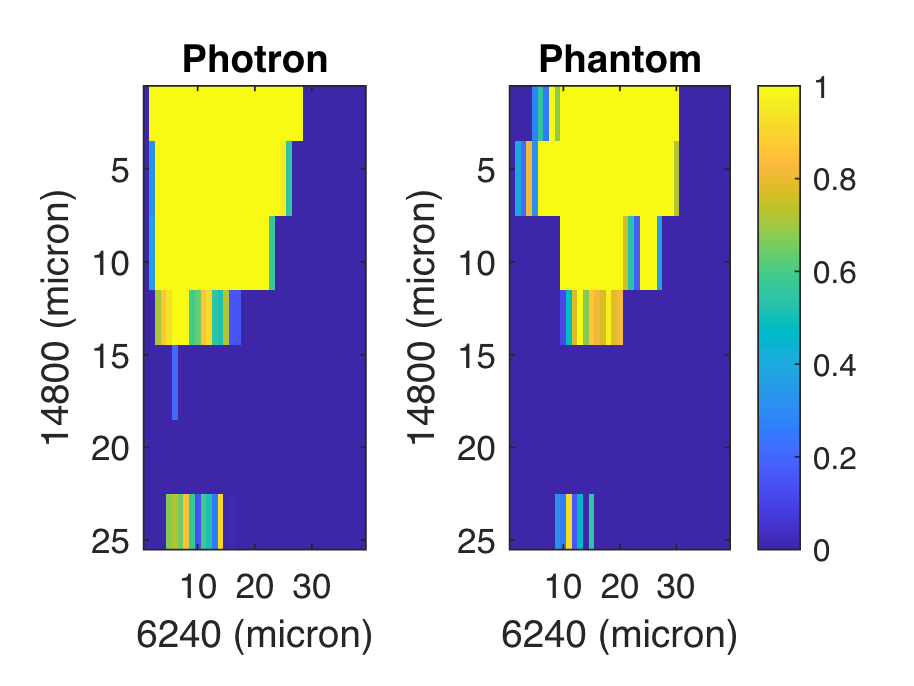


t =0.98;

current1 = normalized1(:,:,round(t*fpms(1))+1);
current2 = normalized2(:,:,round(t*fpms(1))+1);

tiledlayout(1,2);

nexttile;
imagesc(current1);
caxis([0 1]);

title("Photron");
xlabel(micronsPerPixel(2) * size(current1,2) + " (micron)");
ylabel(micronsPerPixel(2) * z2xRatio* size(current1,1) + " (micron)");


nexttile;
imagesc(current2);
caxis([0 1]);
colorbar;

title("Phantom");
xlabel(micronsPerPixel(2) * size(current2,2) + " (micron)");
ylabel(micronsPerPixel(2) * z2xRatio* size(current2,1) + " (micron)");

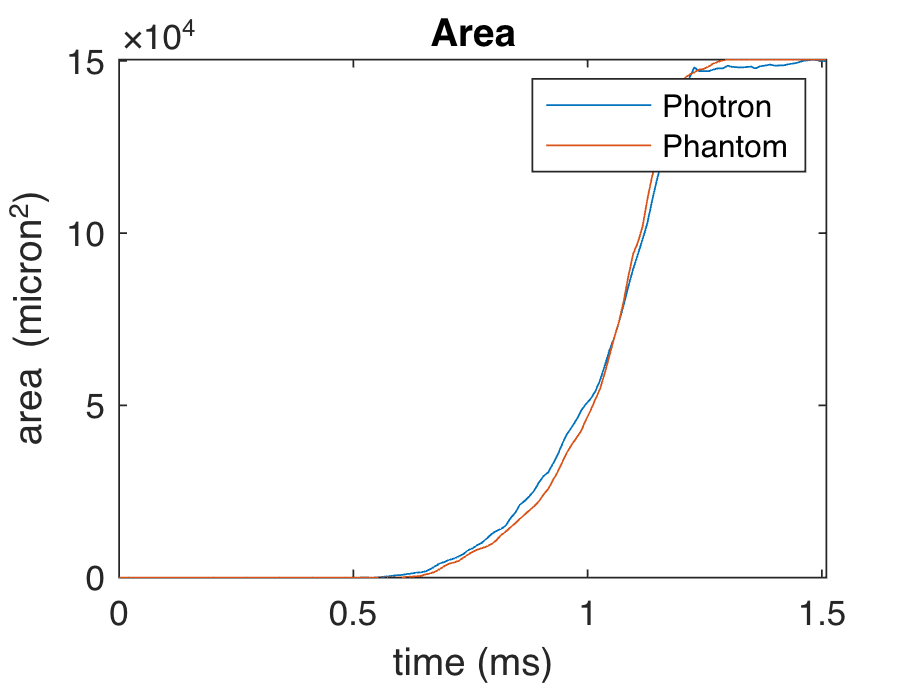

timeSize = size(normalized1,3);
timeLine = linspace(0,totalTime,timeSize);

[Area1,Perimeter1,Beta1] = GetParameters(normalized1,micronsPerPixel(1));
[Area2,Perimeter2,Beta2] = GetParameters(normalized2,micronsPerPixel(1));

figure;
plot(timeLine, Area1);
hold on;
plot(timeLine, Area2);
title("Area");
xlabel("time (ms)");
ylabel("area (micron^2)");
legend("Photron", "Phantom");
hold off;

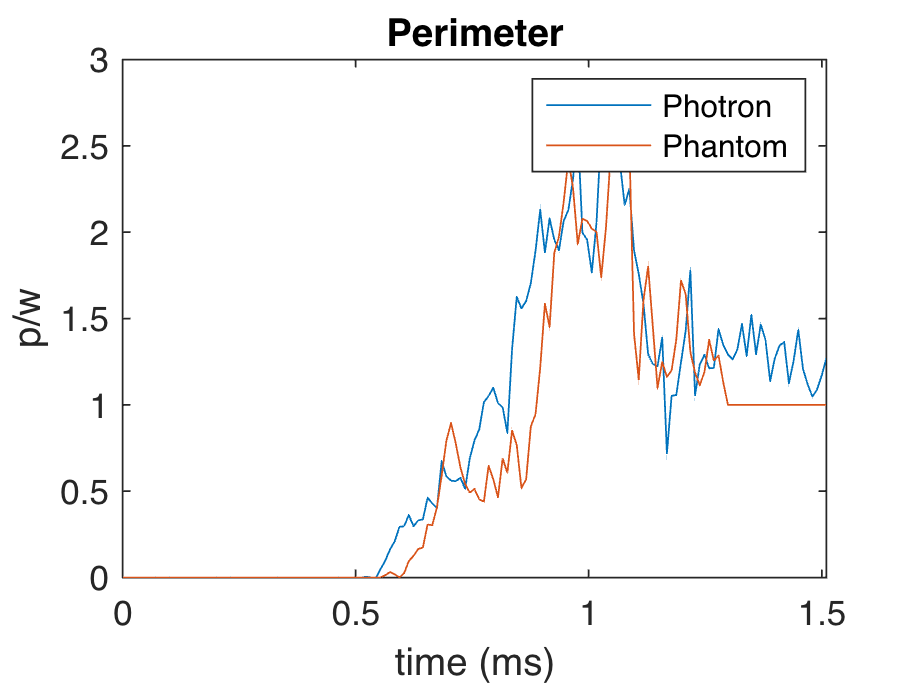


plot(timeLine, Perimeter1);
hold on;
plot(timeLine, Perimeter2);
title("Perimeter");
xlabel("time (ms)");
ylabel("p/w");
legend("Photron", "Phantom");
hold off;

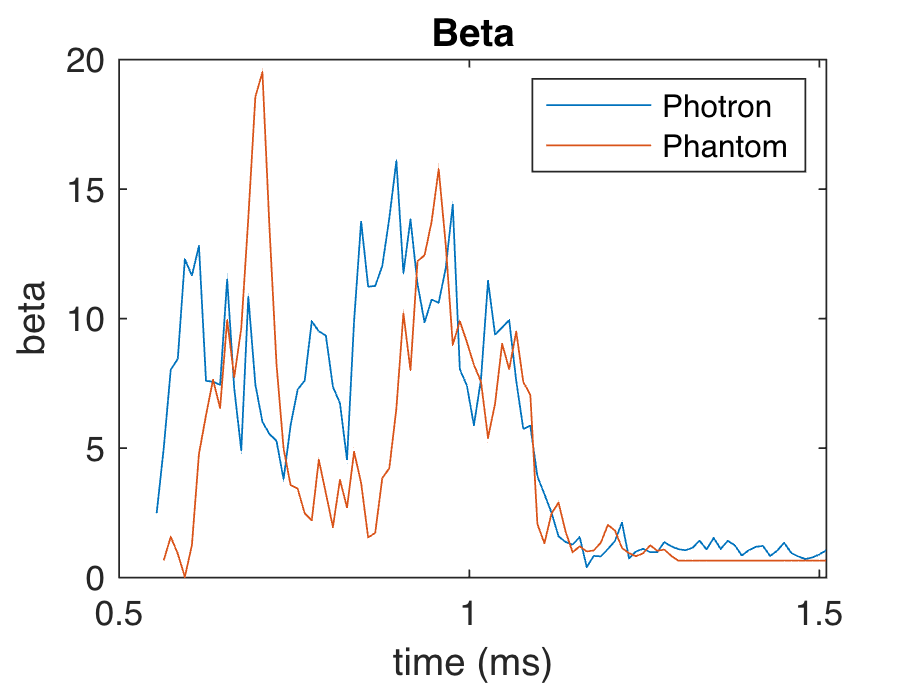


plot(timeLine, Beta1);
hold on;
plot(timeLine, Beta2);
title("Beta");
xlabel("time (ms)");
ylabel("beta");
legend("Photron", "Phantom");
hold off;

function Normalized=NormalizeMat(mat, minVal, maxVal)

    Normalized = zeros(size(mat));
    
    for i=1:size(mat,1)
        for j=1:size(mat,2)
            for k=1:size(mat,3)
                current = mat(i,j,k);
    
                if(current > maxVal)
                    if (j == size(mat,2))
                        result = 0.5;
                    else
                        result = 1;
                    end
                
                elseif (current < minVal)
                    result = 0;
                else
                    result = (current - minVal)/(maxVal - minVal);
                end
    
                Normalized(i,j,k) = result;
            end
        end
    end
end

function [Area, Perimeter, Beta] = GetParameters(mat, scaling)
    Area = zeros(size(mat,3),1);
    Perimeter = zeros(size(mat,3),1);

    for t=1:size(mat,3)
        currentMat = mat(:,:,t);
        Area(t) = sum(currentMat,'all') * scaling * scaling;
    
        currentPerimeter = 0;
        for i=1:size(currentMat,1)
            for j=1:size(currentMat,2)
                currentPixel = currentMat(i,j);
                currentPerimeter = currentPerimeter + 2 * (0.5 - abs(currentPixel - 0.5)) * scaling;
            end
        end
    
        Perimeter(t) = currentPerimeter;
    end

    Beta = (Perimeter .^2) ./ Area;

    Perimeter = Perimeter / (scaling * size(mat,1));
end